# AMINATA DANIOKO  

# AMAT 592  HW 1

## Data Description: Part 1

% Loading the data 
load tremor.mat


## Question 1: Indices of observations

% Find the indices of observations in class 0 appaers below 
figure
I = find (ttr == 0)

I =     90
    91
    92
    93
    94
    95
    96
    97
    98
    99


% The original data is plotted in blue for the indices of oberservation 0 
scatter(Xtr(I,1), Xtr(I,2), 10, 'b')
hold on

% Use the variable J to find the indices of observations in class 1 
J = find (ttr == 1)

J =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


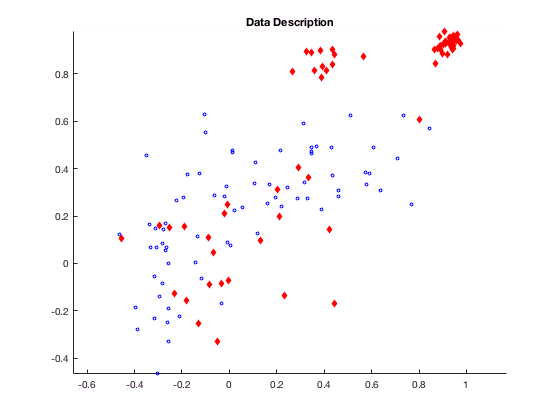

% The variable J is plotted in red points for class 1 of the indices observation and the variable I is represented in blue
scatter(Xtr(J,1), Xtr(J,2),'filled','d', 'r') 
axis equal
hold on 
title('Data Description')

% The graph above displays the combinations of both of the indices observations of class 0 and class 1




## Question 2: Mean, Standard deviation and covariance

% Find the mean of the feature as a whole and for each of the classes

meanXtrc11 = mean(Xtr(I,1))

meanXtrc11 = 0.0699

meanXtrc12 = mean(Xtr(I,2))

meanXtrc12 = 0.2252

meanXtrc21 = mean(Xtr(J,1))

meanXtrc21 = 0.5576

meanXtrc22 = mean(Xtr(J,2))

meanXtrc22 = 0.6550

meanXtrc1  = mean(Xtr(:,1))

meanXtrc1 = 0.3124

meanXtrc2  = mean(Xtr(:,2))

meanXtrc2 = 0.4389


% Find the standard deviation of the feature as a whole and for each class

stdXtrc11 = std(Xtr(I,1))

stdXtrc11 = 0.3360

stdXtrc12 = std(Xtr(I,2))

stdXtrc12 = 0.2404

stdXtrc21 = std(Xtr(J,1))

stdXtrc21 = 0.4350

stdXtrc22 = std(Xtr(J,2))

stdXtrc22 = 0.4022

stdXtrc1  = std(Xtr(:,1))

stdXtrc1 = 0.4580

stdXtrc2  = std(Xtr(:,2))

stdXtrc2 = 0.3941

% Findng the covariance matrix of the feature using the Xtr data set

covXtr = cov(Xtr(:,1),Xtr(:,2))

covXtr =     0.2098    0.1525
    0.1525    0.1553



% Find the correlation between variables x1 and x2 with all the samples
% togther. 

corrXtr   = corr(Xtr(:,1), Xtr(:,2))

corrXtr = 0.8449

corrXtrc1 = corr(Xtr(:,1))

corrXtrc1 = 1

corrXtrc2 = corr(Xtr(:,2))

corrXtrc2 = 1

## Question 3: Standardization

% Standardizing the data by mean-centering it and dividing by the standard
% deviation of the relevant variable.
% defining the mean of the Xtr classifier 

xbar = mean(Xtr) 

xbar =     0.3124    0.4389


% Standardization  of the data
[N, D] = size(Xtr)

N = 179

D = 2

Y = Xtr - repmat(xbar, N, 1)   % mean-centering the mean of the data

Y =     0.6338    0.5207
    0.0143    0.4548
    0.0734    0.4583
    0.1221    0.4636
    0.6618    0.4870
    0.6122    0.4925
    0.6231    0.4781
    0.6185    0.5124
    0.1319   -0.6063
   -0.3165   -0.5089


 
S = cov(Xtr)                 % This is the covariance of the variables

S =     0.2098    0.1525
    0.1525    0.1553


temp = diag(S)

temp =     0.2098
    0.1553


D = diag(temp)

D =     0.2098         0
         0    0.1553


Z = Y*D ^(-1/2)            % The Standardization of the data 

Z =     1.3838    1.3212
    0.0312    1.1539
    0.1603    1.1629
    0.2667    1.1764
    1.4449    1.2358
    1.3366    1.2498
    1.3604    1.2131
    1.3504    1.3003
    0.2881   -1.5384
   -0.6910   -1.2914


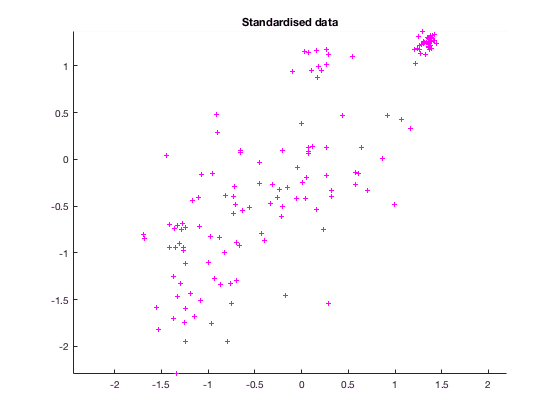

% Plotting the standardised data and with mean and covariace matrix
figure    
scatter(Z(:,1),Z(:,2),10,'m','+')
axis equal
hold on
title('Standardised data')